clear;clc;close all
layerfolder='../data/layers/';%Route to folder with ambiental data
Dimensions = ReadLayers(layerfolder); %The 19 environmental variables for all the map

----Reading layers----
Elapsed time is 8.999138 seconds.


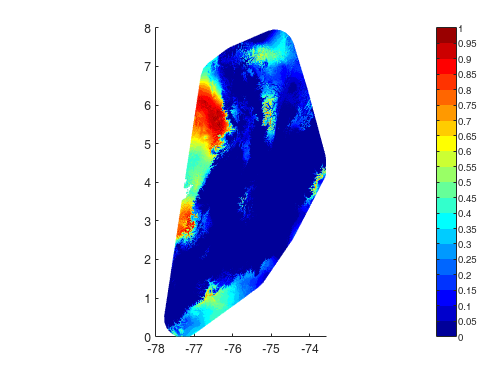

InfoInitialPoint = InitialPoint(Dimensions); %Generate a initial point to generate a niche
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true); %Generate the niche based on the initial point

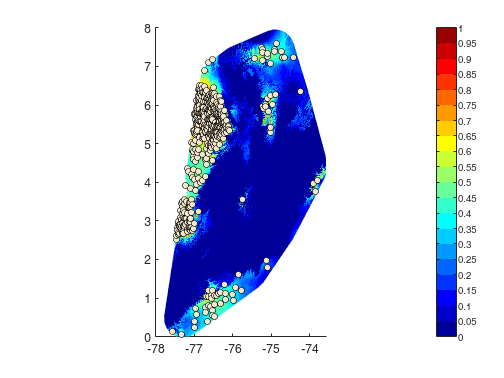

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 500, -3, true, 'GenSP', true, true); %Generate samples based on the generated niche

----Finding clusters----


1 clusters identified


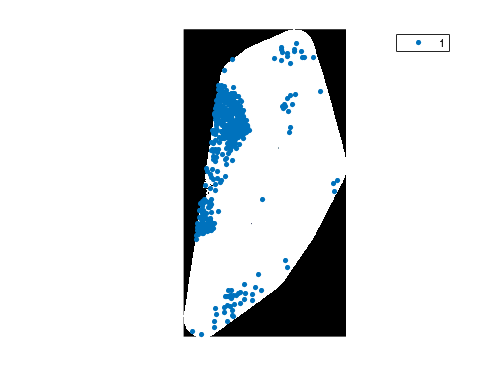

Elapsed time is 7.460049 seconds.
----Finding correlation----
Elapsed time is 13.939489 seconds.
----Creating predictors----
¡All done!
Elapsed time is 14.773031 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false); %associates the sampled data to its environmental factors

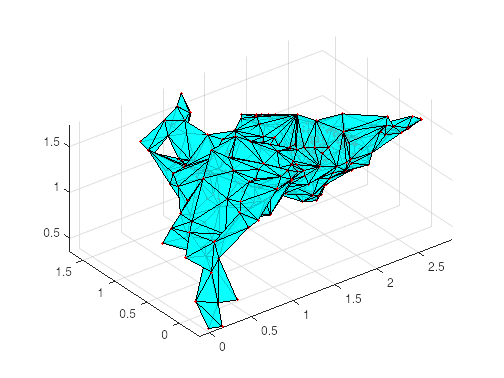

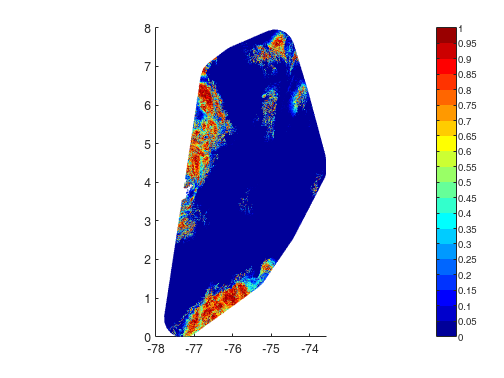

close all, clf
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers

%ColoringBorder generates classifier object with atributes nodes = environmental variables
%for each frontier point, T2 = all environmental variables for each sample,
%index = index in T2 of all frontier points, radius = distance form each
%sample to the closest frontier point and normalizers = the normalizers
%used for noramilzing new points for evaluation
classA = ColoringBorder(data,1,show,outlier,outlier2); 

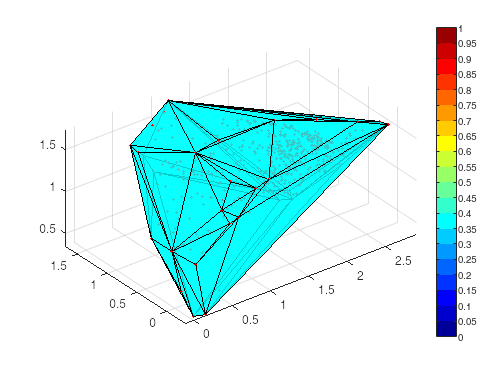

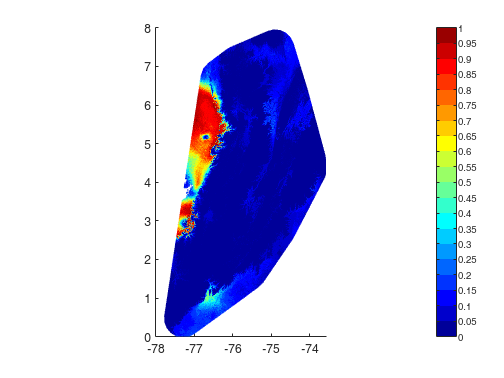

classB = ColoringRadius(data,0,show,outlier,outlier2); 

MapMetric(MapInfo.Map,classA.map,false) %accuracy of the generated colored map compared to the the original niche

ans =     0.9484    0.7898


MapMetric(MapInfo.Map,classB.map,false) 

ans =     0.9127    0.8937


newInfo = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true);
[dataNew,outland] = bnm_prep(newInfo, Dimensions, false, 0.7, false, false);
newPoints(dataNew{1},class)

dataf = bnm_modeling(data, '', false, 4, false);

----Modeling----


ij = 1

-Model 1
Elapsed time is 1.904755 seconds.


% Puntos core: 4c para el metodo hecho mal
% Calcular la distancia desde PCA3: metodo bien hecho